clc; clear;
global Q; global R; global u;
global weights;


Q = [1 0; 0 1];
R = 1;
x0 = [1 2 0]; % x3 is cost value V
xx = [x0]; % tracking x and cost value

uu = 0;
weights = [-2 0 2]';
tracking_weight = [weights];

T = 0.1;
SS = 0.01;
nop = 3;
Fsamples = 40;
j = 0;
tol = 1e-4;
tt = 0;

for k=1:Fsamples
    j = j + 1;
    tspan = 0:SS:T;
    [t,x]= ode23('irl_2ode_nonlinear',tspan,x0);
    xx = [xx; x];
    tt = [tt; t + T*(k-1)];
    x1 = x(length(t),1:2);
%     uu = [uu u];
    phix0 = phi_fn(x0(:,1:2));
    phix1 = phi_fn(x1);

    X(j,:) = phix0 - phix1;
    
    Y(j,:) = x(length(t),3) - x(1,3);
    
    x0 = [x(length(t),1:2),x(length(t),3)];

    if mod(k,nop) == 0 && norm(X) > tol
        weights = pinv(X)*Y;

       tracking_weight = [tracking_weight weights];

        P=[ weights(1)    weights(2)/2  
            weights(2)/2  weights(3)];
        jj = 1;
        X = zeros(nop,3);
        Y = zeros(nop,1);
        j = 0;
    end
end

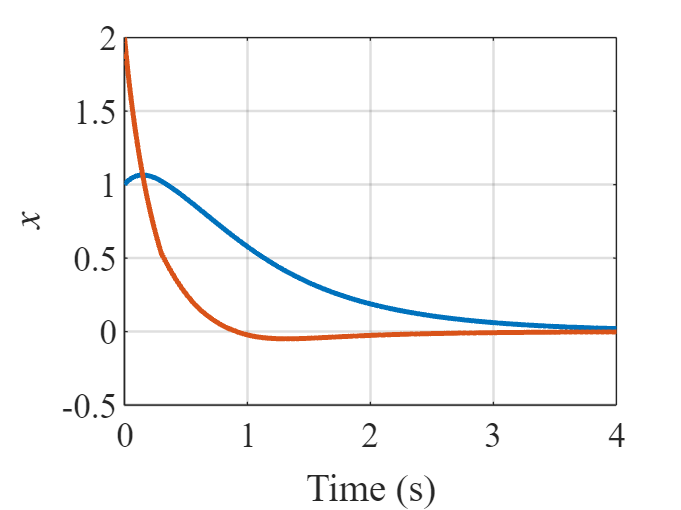

% result
figure(1);
grid on; % states 
plot(tt,xx(:,1),'linewidth',2)
grid on
hold on
plot(tt,xx(:,2),'linewidth',2)
xlabel('Time (s)');
ylabel('$x$','Interpreter','latex');
set(gca,'FontName','Times New Roman','FontSize',14,'linewidth',1);
figure(1), hold off;

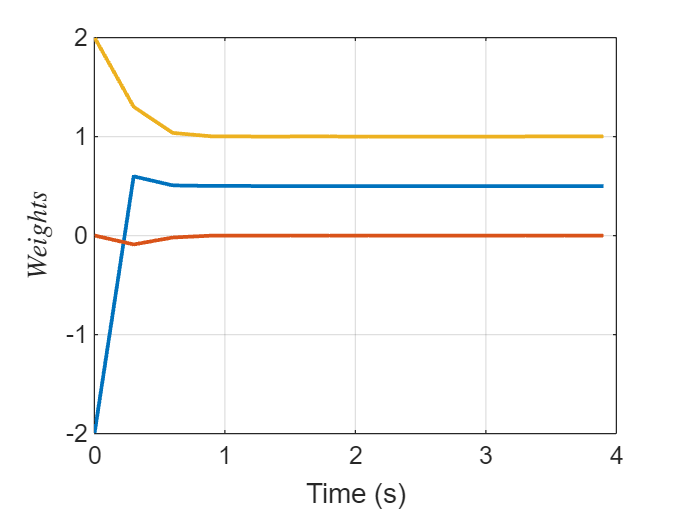

figure(2),  % states 
grid on
plot(0.3*((1:size(tracking_weight,2))-1),tracking_weight(1,:),'linewidth',1.5)
hold on
plot(0.3*((1:size(tracking_weight,2))-1),tracking_weight(2,:),'linewidth',1.5)
plot(0.3*((1:size(tracking_weight,2))-1),tracking_weight(3,:),'linewidth',1.5) 
grid on
xlabel('Time (s)');
ylabel('$Weights$','Interpreter','latex');
figure(2), hold off

weights

weights =     0.5000
   -0.0000
    1.0000
